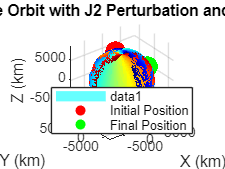

%MAE 180 PROJ S-3 TEAM CODE

clc
clear
format long

%% Common parameters for both runs
lat = 32.8811913;    % Site latitude (phi) in degrees
alt = 111E-3;        % Site altitude in km
JD_prop = 2460542.7792; % Propagation Julian Date (second value given on file)

%% First Run: Group S-3 (ADVENTURE 1)
% Days (JD), right ascension (ra), declination (dec), and local sidereal time (lst)
JD  = [2460262.842373029;
       2460262.842893863;
       2460262.843414696];
   
ra  = [135.514066681081;
       148.057402685433;
       165.762330451468];

dec = [29.155447177193;
       45.578290874916;
       56.881276513171];

lst = [59.199692009582;
       59.387705356210;
       59.575718703254];

% Calculate orbit parameters for Group S-3
[r0, v0, oe0, r, v, oe] = OrbitComp(lat, lst, alt, ra, dec, JD, JD_prop);